# Interactive Plane Simulation

When simulating an aircraft, our goal is to break it down into as few varialbes as possible and simplify the model. By controlling these geometric and mission variables, we can predict various aerodynamic performances. The goal is to be able to simulate a mock up competition plane. For every variable you change, you are not only shiting the aerodynmic characteristics of the plane, but also its mass distribution. You can make a really big plane, it'll just be heavy! Some notes on these variables:

- A positive dihedral directs the wings upwards

- A negative incidence angle on the hstab points it downwards

- A negative nose postition means it's in front of the leading edge

%% ── Fill in these parameters ──────────────────────────────────────────────
geom.wing_span    = 1.2;   % [m]   full wing span
geom.wing_AR      = 4;   % [-]   wing aspect ratio
geom.dihedral     = 0; % [deg] upwards dihedral angle
geom.htail_span   = 0.4;   % [m]   full horizontal tail span
geom.htail_AR     = 2.5;   % [-]   horizontal tail aspect ratio
geom.htail_incidence = -2;   % [deg] horizontal tail incidence (negative = trailing edge up, e.g. -2.0)
geom.vtail_height = 0.2;   % [m]   vertical tail height
geom.vtail_AR     = 1.5;   % [-]   vertical tail aspect ratio
geom.tail_arm     = 0.85;   % [m]   AC-to-AC tail moment arm
geom.nose_x       = -0.25;   % [m]   motor+prop x-position from wing LE (negative = forward)
geom.n_ducks      = 3;   % [-]   number of duck payloads
geom.n_pucks      = 1;   % [-]   number of puck payloads

% Building mass layout from geometries


=== Mass Breakdown ===
  Component             m (kg)    x (m)    z (m)
  ------------------------------------------------
  Wing                   0.730   +0.135  +0.0000
  Htail                  0.086   +0.957  +0.0000
  Vtail                  0.036   +0.945  +0.0000
  Tail spar              0.183   +0.442  +0.0000
  Fuselage               0.428   +0.025  +0.0000
  Motor+Prop             0.390   -0.250  -0.0250
  Nosecone               0.152   -0.210  +0.0000
  Battery                0.690   -0.150  -0.0250
  Receiver               0.024   -0.100  +0.0000
  Servo bat.             0.045   -0.120  +0.0000
  Gyro                   0.021   -0.130  +0.0000
  Main gear              0.125   +0.120  -0.0250
  Front gear             0.105   -0.125  -0.0250
  3 Duck(s)              0.348   +0.191  +0.0000
  1 Puck(s)              0.190   +0.084  +0.0000
  ------------------------------------------------
  TOTAL / CG             3.552  +0.0414  -0.0092

  CG: 0.0414 m = 13.8% MAC
  Ixx = 0.089

mass = defineMassConfig(geom);

## Mass Distribution and Plane Diagram

We haven't been really using freedom units so far, but even then, it's probably best we see the plane we're desining. That way, we can actually compare it with our intuition and see the effects of our changes. Press run to generate the mass distribution plots. You can see the placements of every component, as well as the CG. An "ideal" plane will have the CG at roughly the quarter-chord (25% MAC), but in AVL simulatinos that may be slightly different. 

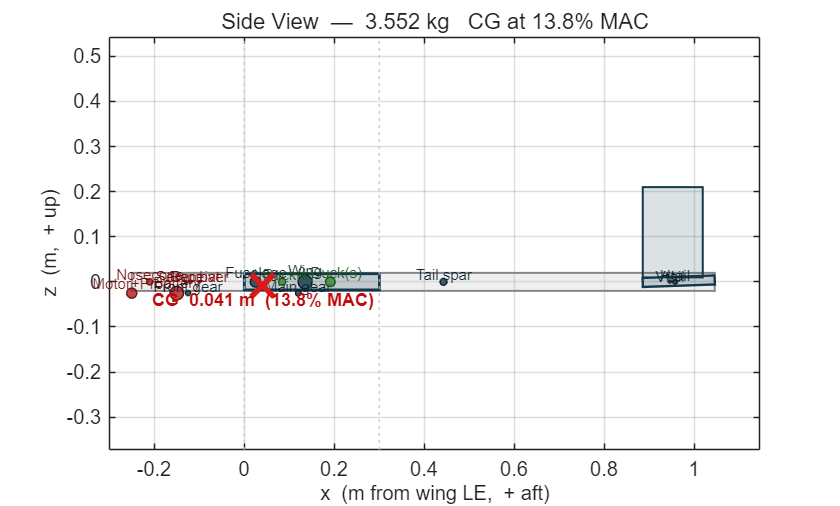

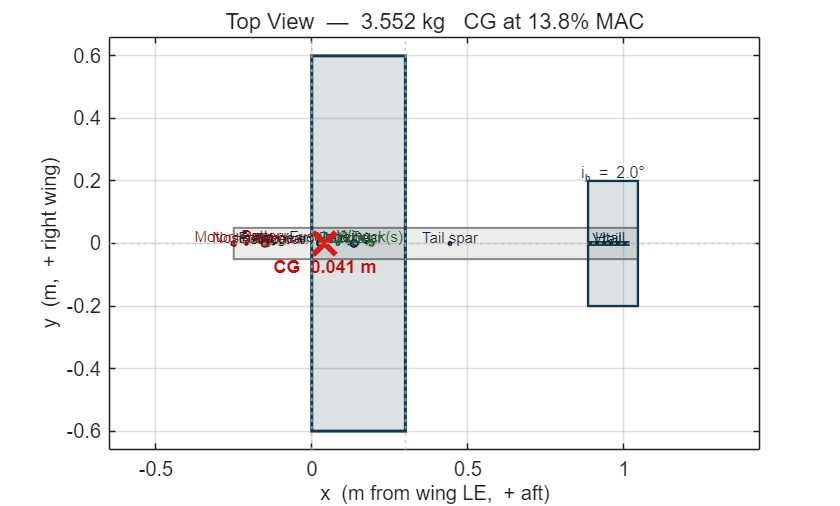

plotMassLayout(mass);

## Running AVL

Now it's time to run AVL! You've all learned XFLR5, and AVL does pretty much the same. The nice thing about it is it's run entirely through the CLI, so MATLAB can just do it! In the previous modules, you built up the mass model of the plane. Now, we just have to evaluate it. AVL is going to calculate stability and aerodynamic characteristics, but these vary a bit based on flight speed. To simulate cruise conditions, 27 m/s is a good estimate. For takeoff, around 15 m/s is fine.

In this section, take special note to the two bottom values: Elevator, and SM. Elevator dictates the trim required (elevator deflection) to keep the plane balanced at our set speed. The SM refers to the static margin, which we typically want between 10 and 25 percent.

V =27;        % [m/s] aircraft velocity
 
aircraft = massToAVL(mass);         % AVL-ready struct


=== Aircraft Config ===
  Wing:    span = 1.200 m   chord = 0.3000 m   AR = 4.00   S = 0.3600 m²
  Htail:   span = 0.400 m   chord = 0.1600 m   x_le = 0.8850 m
  Vtail:   h    = 0.200 m   chord = 0.1333 m   x_le = 0.8850 m
  Tail arm = 0.8500 m   Vht = 0.504   Vvt = 0.052
  Mass     = 3.552 kg
  CG       = 0.0414 m (13.8% MAC)


out      = runAVL(aircraft, V);     % run AVL

Flight condition:
  V         = 27.00 m/s
  rho       = 1.2250 kg/m3
  mass      = 3.552 kg
  CL_cruise = 0.2168
AVL geometry file written: C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo.avl
Open in AVL with:  load C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo.avl
Then view with:    oper -> g
Mass file written: C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo.mass
Running AVL...
Progress: case % done
Done. Output files:
  Stability: C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\dfo_stability.txt
  AVL log:   C:\Users\kaspe\OneDrive\Cornell\All\Coding\end-of-semester-25-26\src\avl\avl_log.txt


avl      = parseAVLOutput(out.stability_file);


=== AVL Results ===
  Trim alpha     = -1.015 deg
  Trim elevator  = +2.574 deg
  CL             =  0.2168
  CDi (Trefftz)  =  0.00394  [induced only -- CD0 from sizing script]
  Span eff. e    =  NaN
  Neutral pt Xnp =  0.1129 m

  --- Pitch ---
  CLa  = +3.8121 /rad
  Cma  = -0.0366 /rad   (< 0 = stable)
  Cmq  = -7.8469 /rad

  --- Lateral/Directional ---
  Clb  = -0.0158 /rad
  Cnb  = +0.0986 /rad   (> 0 = weathercock stable)
  Clp  = -0.3474 /rad   (roll damping)
  Cnr  = -0.1470 /rad   (yaw  damping)
  Spiral ratio   =  0.279  (> 1 = spirally stable)


modes    = computeAVLModes(avl, aircraft, V);


=== Flight Dynamics Modes ===
  Phugoid         σ = -0.0215   ω = +0.1911 rad/s   [stable]
  Short Period    σ = -4.0500   (non-oscillatory)   [stable]
  Dutch Roll      σ = -0.8398   ω = +6.6445 rad/s   [stable]
  Roll            σ = -482.1087   (non-oscillatory)   [stable]
  Spiral          σ = +0.0632   (non-oscillatory)   t2 = 10.96 s  [UNSTABLE]


fprintf('=== Operating Point ===\n')

=== Operating Point ===


fprintf('  V        = %.3f m/s\n',  V)

  V        = 27.000 m/s


fprintf('  alpha    = %.3f deg\n',  avl.alpha)

  alpha    = -1.015 deg


fprintf('  CL       = %.5f\n',      avl.CL)

  CL       = 0.21679


fprintf('  CDi      = %.5f\n',      avl.CDi)

  CDi      = 0.00394


fprintf('  Elevator = %.3f deg\n',  avl.elevator)

  Elevator = 2.574 deg


fprintf('  SM       = %.1f%% MAC\n', (avl.Xnp - aircraft.xref) / aircraft.Cref * 100)

  SM       = 23.8% MAC


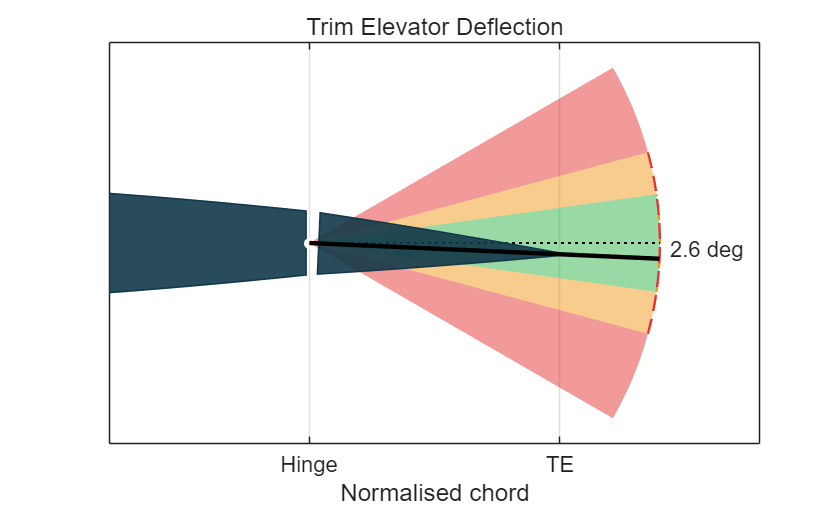


%% Elevator Deflection
% When the plane is flying straight and level, the elevator has to hold a
% specific angle to keep things trimmed. That angle is what AVL just gave
% us. A small deflection is great. A big one means the elevator is working
% overtime just to stay level, which leaves you with less authority if you
% actually need to maneuver.
%
% The bands below are a rough guide. A few degrees either way is basically
% free. Once you start pushing past ten, you are burning a nontrivial chunk
% of your elevator range just to cruise. Past fifteen and you should
% seriously think about moving the CG or resizing the tail.

elev_deg = avl.elevator;   % trim elevator deflection [deg]

% --- geometry ---
% Airfoil runs from x=0 (LE) to x=1 (TE), hinge at x=0.75
% Elevator chord fraction = 0.25 (trailing 25%)
x_hinge = 0.75;

% --- NACA 0012-ish symmetric profile (normalised chord 0..1) ---
N     = 80;
x_af  = linspace(0, 1, N);
t     = 0.12;   % thickness ratio
y_top =  5*t * (0.2969*sqrt(x_af) - 0.1260*x_af - 0.3516*x_af.^2 ...
                + 0.2843*x_af.^3 - 0.1015*x_af.^4);
x_full = [x_af,        fliplr(x_af)];
y_full = [y_top,       -fliplr(y_top)];

% Split into fixed (fore) and elevator (aft) sections
fixed_mask = x_af <= x_hinge;
elev_mask  = x_af >= x_hinge;

x_fixed_top = x_af(fixed_mask);  y_fixed_top = y_top(fixed_mask);
x_elev_top  = x_af(elev_mask);   y_elev_top  = y_top(elev_mask);

% Rotate elevator section about hinge point by -elev_deg
%   positive deflection = trailing edge DOWN (convention)
theta = deg2rad(-elev_deg);
R     = [cos(theta), -sin(theta); sin(theta), cos(theta)];

elev_coords_top = R * [(x_elev_top - x_hinge); y_elev_top];
elev_coords_bot = R * [(x_elev_top - x_hinge); -y_elev_top];

xe_top = elev_coords_top(1,:) + x_hinge;
ye_top = elev_coords_top(2,:);
xe_bot = elev_coords_bot(1,:) + x_hinge;
ye_bot = elev_coords_bot(2,:);

% Full outline of fixed section
x_fixed = [x_fixed_top, fliplr(x_fixed_top)];
y_fixed  = [y_fixed_top, -fliplr(y_fixed_top)];

% Full outline of deflected elevator (close the shape at hinge)
x_elev_patch = [xe_top, fliplr(xe_bot)];
y_elev_patch  = [ye_top, fliplr(ye_bot)];

% --- wedge bands ---
% Bands radiate from hinge point, rightward only (angle measured from 0-deg line)
% green:   0..8 deg  (above AND below)
% yellow:  8..14 deg
% red:     14..25 deg  (cap at 25 for display)
wedge_r   = 0.35;   % radius of wedge arcs in chord units
ang_bands = [0, 8, 15, 30];   % deg boundaries
band_cols = [0.20 0.70 0.30;   % green
             0.95 0.60 0.10;   % yellow
             0.90 0.20 0.20];  % red

figure;
hold on;

% Draw wedge bands (both +ve and -ve sides)
for b = 1:3
    a1 = deg2rad(ang_bands(b));
    a2 = deg2rad(ang_bands(b+1));
    arc_ang = linspace(a1, a2, 40);

    % Upper wedge (+ve angles above chord line)
    wx = [x_hinge, x_hinge + wedge_r*cos(arc_ang), x_hinge];
    wy = [0,       wedge_r*sin(arc_ang),             0      ];
    fill(wx, wy, band_cols(b,:), 'FaceAlpha', 0.50, ...
         'EdgeColor', 'none', 'HandleVisibility', 'off')

    % Lower wedge (mirror)
    fill(wx, -wy, band_cols(b,:), 'FaceAlpha', 0.50, ...
         'EdgeColor', 'none', 'HandleVisibility', 'off')
end

% Dashed arc boundary lines
for b = 2:3
    arc_ang = linspace(-deg2rad(ang_bands(b)), deg2rad(ang_bands(b)), 60);
    xarc = x_hinge + wedge_r * cos(arc_ang);
    yarc = wedge_r * sin(arc_ang);
    if b == 2
        col = [0.95 0.60 0.10];
    else
        col = [0.90 0.20 0.20];
    end
    plot(xarc, yarc, '--', 'Color', col, 'LineWidth', 1.2, 'HandleVisibility', 'off')
end

% Neutral chord reference line from hinge
plot([x_hinge, x_hinge + wedge_r], [0, 0], ...
     'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off')

% --- draw airfoil ---
fill(x_fixed, y_fixed, [0.07 0.22 0.29], ...
     'FaceAlpha', 0.90, 'EdgeColor', [0.07 0.22 0.29], 'LineWidth', 0.8, ...
     'HandleVisibility', 'off')
fill(x_elev_patch, y_elev_patch, [0.07 0.22 0.29], ...
     'FaceAlpha', 0.90, 'EdgeColor', [0.07 0.22 0.29], 'LineWidth', 0.8, ...
     'HandleVisibility', 'off')

% Hinge point dot
plot(x_hinge, 0, 'wo', 'MarkerFaceColor', 'w', 'MarkerSize', 5, ...
     'HandleVisibility', 'off')

% Actual deflection line from hinge
theta_act = deg2rad(-elev_deg);
plot([x_hinge, x_hinge + wedge_r*cos(theta_act)], ...
     [0,        wedge_r*sin(theta_act)], ...
     'k-', 'LineWidth', 2.2, 'HandleVisibility', 'off')

% Label
text(x_hinge + wedge_r*cos(theta_act) + 0.01, ...
     wedge_r*sin(theta_act) + 0.01, ...
     sprintf('%.1f deg', elev_deg), 'FontSize', 11)

% --- formatting ---
axis equal
xlim([0.55, 1.20])
ylim([-0.20, 0.20])
xlabel('Normalised chord', 'FontSize', 12)
title('Trim Elevator Deflection', 'FontSize', 12, 'FontWeight', 'normal')
set(gca, 'YTick', [], 'XTick', [0, x_hinge, 1], ...
         'XTickLabel', {'LE', 'Hinge', 'TE'}, 'FontSize', 11)
grid on; box on;
hold off;

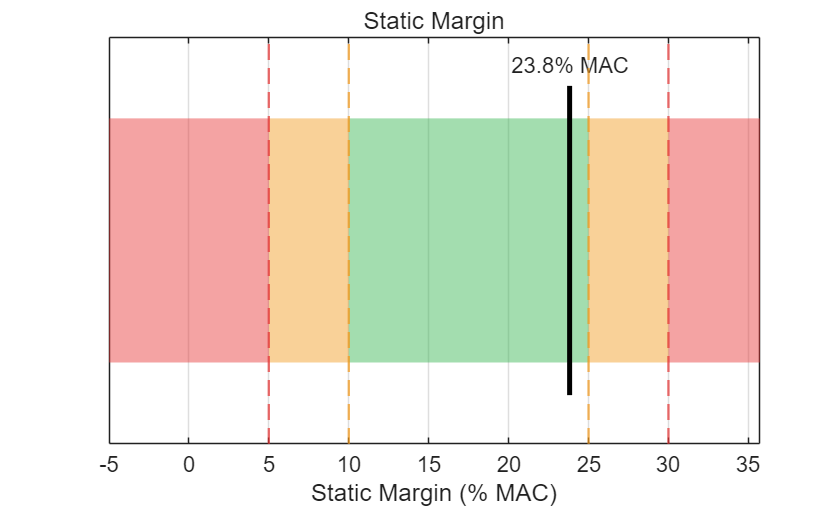

%% Static Margin
% Static margin is the gap between the neutral point and the CG, measured
% as a fraction of the mean chord. It tells you how naturally the plane
% wants to return to level flight after a disturbance. Too little and the
% plane is nearly neutrally stable and very twitchy. Too much and the
% elevator has to fight the tail to pitch up at all.
%
% For a DBF aircraft, somewhere around 10 to 25 percent MAC is the sweet
% spot. You get predictable, stable flight without needing a ton of
% elevator authority to rotate at takeoff. Below 5 percent things get
% anxious. Above 30 percent and Mitch will have a hard time getting the
% nose up on the runway.

SM_pct = (avl.Xnp - aircraft.xref) / aircraft.Cref * 100;  % [% MAC]

% fprintf('Static Margin = %.1f%% MAC\n', SM_pct)

% --- colour bands (% MAC) ---
% red:     SM < 5  or  SM > 30
% yellow:  5  <= SM < 10  or  25 < SM <= 30
% green:   10 <= SM <= 25

figure;
hold on;

bar_y = [0.2, 0.2, 0.8, 0.8];
x_max = max(abs(SM_pct) * 1.5, 35);
x_min = min(-5, SM_pct - 5);

% Red bands
patch([x_min,  5,  5, x_min], bar_y, [0.90 0.20 0.20], ...
      'FaceAlpha', 0.45, 'EdgeColor', 'none', 'HandleVisibility', 'off')
patch([30, x_max, x_max, 30], bar_y, [0.90 0.20 0.20], ...
      'FaceAlpha', 0.45, 'EdgeColor', 'none', 'HandleVisibility', 'off')

% Yellow bands
patch([ 5, 10, 10,  5], bar_y, [0.95 0.60 0.10], ...
      'FaceAlpha', 0.45, 'EdgeColor', 'none', 'HandleVisibility', 'off')
patch([25, 30, 30, 25], bar_y, [0.95 0.60 0.10], ...
      'FaceAlpha', 0.45, 'EdgeColor', 'none', 'HandleVisibility', 'off')

% Green band
patch([10, 25, 25, 10], bar_y, [0.20 0.70 0.30], ...
      'FaceAlpha', 0.45, 'EdgeColor', 'none', 'HandleVisibility', 'off')

% Threshold lines
xline( 5,  '--', 'Color', [0.90 0.20 0.20], 'LineWidth', 1.2, 'HandleVisibility', 'off')
xline(30,  '--', 'Color', [0.90 0.20 0.20], 'LineWidth', 1.2, 'HandleVisibility', 'off')
xline(10,  '--', 'Color', [0.95 0.60 0.10], 'LineWidth', 1.2, 'HandleVisibility', 'off')
xline(25,  '--', 'Color', [0.95 0.60 0.10], 'LineWidth', 1.2, 'HandleVisibility', 'off')

% SM needle
plot([SM_pct SM_pct], [0.12 0.88], ...
     'k-', 'LineWidth', 2.5, 'HandleVisibility', 'off')
text(SM_pct, 0.90, sprintf('%.1f%% MAC', SM_pct), 'VerticalAlignment', 'bottom', 'FontSize', 11, HorizontalAlignment='center')

xlim([x_min x_max])
ylim([0 1])
xlabel('Static Margin (% MAC)', 'FontSize', 12)
title('Static Margin', 'FontSize', 12, 'FontWeight', 'normal')
set(gca, 'YTick', [], 'FontSize', 11)
grid on; box on;
hold off;

## Longitudinal Stability

There are two types of stability modes: longitudinal, which focuses on the pitch of the aircraft, and lateral, which accounts for yaw and roll. What do we mean by mode? Modes are natural motions the aircraft can go through during flight. For example, if you push a swing it will move up and down until settling down — that's one mode. Planes have six! How we derive these is a long and arduous process, but what matters to us is whether or not they're stable. Imagine if your friend pushed you on a swing and you started gaining more and more speed until eventually the swing just broke. Yep. That's not good for planes either. To visualize modes, we plot eigenvalues on the complex plane. Anything in the left half (negative real part) is stable. Anything in the right half is not.

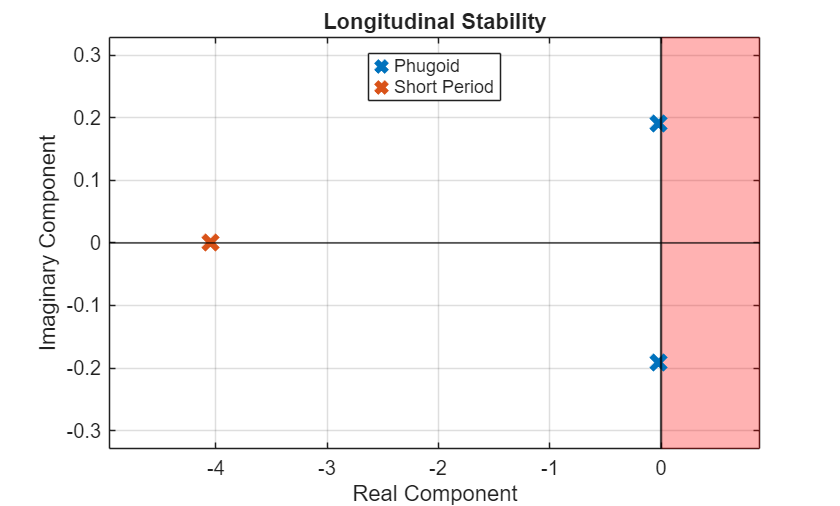

 
lon_modes  = {'Phugoid', 'ShortPeriod'};
lon_labels = {'Phugoid', 'Short Period'};
lon_colors = {'#0072BD', '#D95319'}; % MATLAB default blue, MATLAB default red/orange

% Compute axis limits from actual mode values before drawing anything
all_sig = cellfun(@(k) modes.(k).sigma, lon_modes);
all_omg = cellfun(@(k) abs(modes.(k).omega), lon_modes);

pad_x = max(abs(all_sig)) * 0.2 + 0.1;
pad_y = max(all_omg) * 0.2 + 0.1;

xl = [min(all_sig) - pad_x, max(all_sig) + pad_x];

% Fix ylim issue when omega values are very small or zero
max_omg = max(all_omg);
if max_omg < 0.01
    yl = [-1, 1];
else
    yl = [-(max_omg + pad_y), max_omg + pad_y];
end

figure;
hold on;

patch([0, xl(2), xl(2), 0], [yl(1), yl(1), yl(2), yl(2)], ...
    [1 0 0], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'HandleVisibility', 'off')

yline(0, 'k', 'LineWidth', 0.8, 'HandleVisibility', 'off')
xline(0, 'k', 'LineWidth', 1.2, 'HandleVisibility', 'off')

for k = 1:numel(lon_modes)
    m = modes.(lon_modes{k});

    if abs(m.omega) > 0.01
        plot([m.sigma, m.sigma], [m.omega, -m.omega], 'x', ...
            'MarkerSize', 10, 'LineWidth', 3, ...
            'Color', lon_colors{k}, ...
            'DisplayName', lon_labels{k})
    else
        plot(m.sigma, 0, 'x', ...
            'MarkerSize', 10, 'LineWidth', 3, ...
            'Color', lon_colors{k}, ...
            'DisplayName', lon_labels{k})
    end
end

xlim(xl);
ylim(yl);

xlabel('Real Component');
ylabel('Imaginary Component');
title('Longitudinal Stability');
legend('Location', 'north');
grid on;
box on;
hold off;

## Lateral Stability

In the lateral plots, you'll notice that some modes only have one eigenvalue displayed — they are purely real. If you've suffered through PHYS 2214 Waves, you'll recall that means these values do not oscillate and either exponentially decay or grow. It's here we're most likely to see an instability in the spiral mode. Zoom in on the origin to check whether the spiral sits just barely in the positive x-domain.

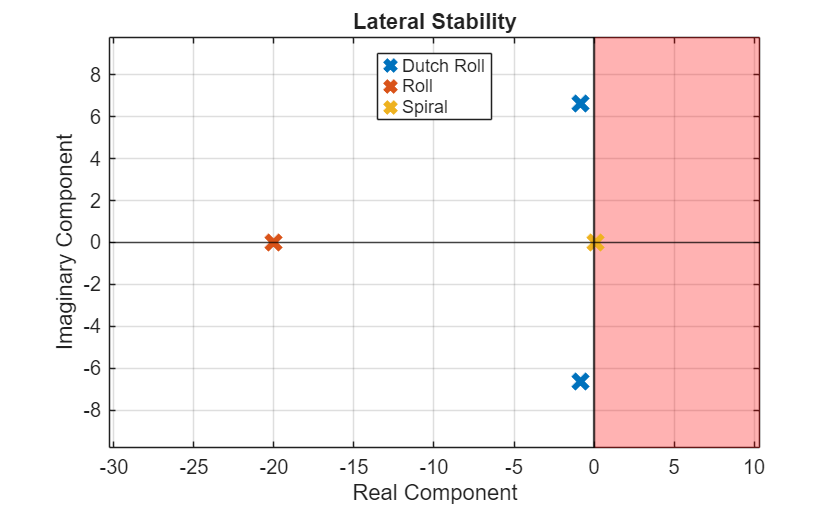

 
lat_modes  = {'DutchRoll', 'Roll', 'Spiral'};
lat_labels = {'Dutch Roll', 'Roll', 'Spiral'};
colors = {'#0072BD', '#D95319', '#EEB220'}; % default blue, red, your yellow

% Clamp roll mode for axis scaling only — it's always far-left and stable
clamp = 20;
all_sig_lat = cellfun(@(k) max(modes.(k).sigma, -clamp), lat_modes);
all_omg_lat = cellfun(@(k) abs(modes.(k).omega), lat_modes);
pad_x = max(abs(all_sig_lat)) * 0.5 + 0.3;
pad_y = max(all_omg_lat) * 0.4 + 0.5;
xl2 = [min(all_sig_lat) - pad_x,  max(all_sig_lat) + pad_x];
yl2 = [-(max(all_omg_lat) + pad_y), max(all_omg_lat) + pad_y];

figure;
hold on;

patch([0, xl2(2), xl2(2), 0], [yl2(1), yl2(1), yl2(2), yl2(2)], ...
    [1, 0, 0], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'HandleVisibility', 'off')

yline(0, 'k', 'LineWidth', 0.8,  'HandleVisibility', 'off')
xline(0, 'k', 'LineWidth', 1.2,  'HandleVisibility', 'off')

for k = 1:numel(lat_modes)
    m    = modes.(lat_modes{k});
    col  = [0.07 0.22 0.29];
    if m.sigma > 0, col = [0.70 0.11 0.11]; end
    % Plot at clamped x if roll is off-scale, with a note
    sig_plot = max(m.sigma, -clamp);
    if abs(m.omega) > 0.01
        plot([sig_plot, sig_plot], [m.omega, -m.omega], 'x', ...
            'MarkerSize', 10, 'LineWidth', 3, 'Color', colors{k}, 'DisplayName', lat_labels{k})
    else
        plot(sig_plot, 0, 'x', ...
            'MarkerSize', 10, 'LineWidth', 3, 'Color', colors{k}, 'DisplayName', lat_labels{k})
        % if m.sigma < -clamp
        %     text(sig_plot, 0.15, sprintf('σ=%.0f', m.sigma), ...
        %         'FontSize', 8, 'Color', colors{k}, 'HorizontalAlignment', 'center')
        % end
    end
end

xlim(xl2); ylim(yl2);
xlabel('Real Component');  ylabel('Imaginary Component');
title('Lateral Stability');
legend('Location', 'north');
grid on; box on; hold off;

## Doubling Times

One other consideration is the doubling time. If a mode is unstable, we want to measure how long it takes for the instability to grow. If it grows very slowly, that's okay, Mitch can just fix it in flight. If it doubles much quicker than a reaction time can allow, that's when we have a problem. Below there will three regions: red, yellow green. You defintely do not want a doubling time less than three seconds, and you should be really cautious of a doubling time below 8. Once you get past ten, you're usually pretty fine. The main concern here is typically the spiral mode.

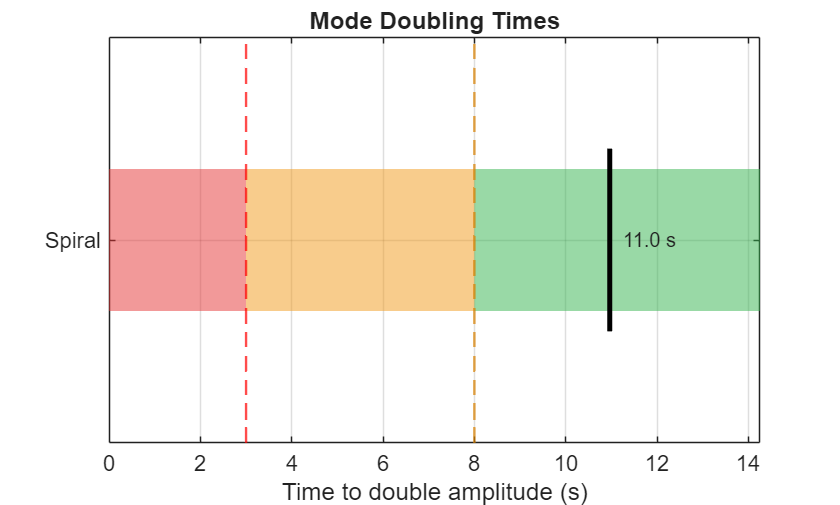

 
mode_names   = {'Phugoid', 'ShortPeriod', 'DutchRoll', 'Roll', 'Spiral'};
label_names  = {'Phugoid', 'Short Period', 'Dutch Roll', 'Roll', 'Spiral'};

unstable_labels = {};
unstable_t2     = [];

for k = 1:numel(mode_names)
    m = modes.(mode_names{k});
    if isfinite(m.t2)
        % fprintf('Mode: %-14s  t2 = %.3f s\n', label_names{k}, m.t2)
        unstable_labels{end+1} = label_names{k};
        unstable_t2(end+1)     = m.t2;
    end
end

if isempty(unstable_labels)
    fprintf('All modes are stable — no doubling times to report.\n')
end

if ~isempty(unstable_labels)
    figure;
    hold on;
    title('Mode Doubling Times')
    xlabel('Time to double amplitude (s)')

    x_max = max(max(unstable_t2) * 1.3, 12);
    bar_h = 0.35;

    for k = 1:numel(unstable_labels)
        t2 = unstable_t2(k);
        y  = [k-bar_h/2, k-bar_h/2, k+bar_h/2, k+bar_h/2];

        patch([0, min(3,x_max), min(3,x_max), 0], y, ...
              [0.90 0.20 0.20], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off')
        if x_max > 3
            patch([3, min(8,x_max), min(8,x_max), 3], y, ...
                  [0.95 0.60 0.10], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off')
        end
        if x_max > 8
            patch([8, x_max, x_max, 8], y, ...
                  [0.20 0.70 0.30], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off')
        end

        plot([t2 t2], [k-bar_h/2-0.05, k+bar_h/2+0.05], ...
             'k-', 'LineWidth', 2.5, 'HandleVisibility', 'off')
        text(t2 + x_max*0.02, k, sprintf('%.1f s', t2), ...
             'VerticalAlignment', 'middle', 'FontSize', 10)
    end

    xline(3, 'r--', 'LineWidth', 1.2, 'HandleVisibility', 'off')
    xline(8, '--', 'Color', [0.85 0.50 0.0], 'LineWidth', 1.2, 'HandleVisibility', 'off')

    set(gca, 'YTick', 1:numel(unstable_labels), ...
             'YTickLabel', unstable_labels, 'FontSize', 11)
    xlim([0 x_max])
    ylim([0.5, numel(unstable_labels) + 0.5])
    grid on; box on;
    hold off;
end

## Polar Data

Instead of just stability, we want to look deeper into the aerodynamics! To do that, we need to bring in a couple constants and propulsion variables. If you're interested, you can un-hide the code here to see what we're importing. If not, just press run!

 
%  Run the AVL pipeline. Everything below reads from aircraft, avl, and V.
addpath('src\')

V_nom           = 22.2;    % battery nominal voltage          [V]
cap_battery     = 4.2;     % battery capacity                 [Ah]
use_battery     = 0.85;    % fraction of battery to use       [-]
Kv              = 520;     % motor Kv                         [RPM/V]
I0              = 1.4;     % motor no-load current            [A]
Rm              = 0.016;   % motor winding resistance         [ohm]
% cruise_throttle = 0.80;    % cruise throttle setting          [-]
prop_id         = 62;      % propeller index in library       [-]
fprintf("Imported battery constants...");

Imported battery constants...


prop_lib_path     = "prop_data_library.mat";
prop_data_library = getPropData(prop_lib_path);
fprintf("Imported prop data...");

Imported prop data...


% CD0 still comes from the sizing program — AVL is inviscid so CDvis = 0.
% Use avl.CDi as the operating point induced drag marker.
CD0 = 0.05896;
e   = 0.75;
rho = 1.225;
g   = 9.81;
fprintf("Imported aerodynamic constants...");

Imported aerodynamic constants...



% fprintf('=== Operating Point ===\n')
% fprintf('  V        = %.3f m/s\n',  V)
% fprintf('  alpha    = %.3f deg\n',  avl.alpha)
% fprintf('  CL       = %.5f\n',      avl.CL)
% fprintf('  CDi      = %.5f\n',      avl.CDi)
% fprintf('  Elevator = %.3f deg\n',  avl.elevator)


## Drag and Velocity

Things are getting real! We want to introduce two types of drag: parasitic and induced. Parasitic drag is due to the form of the aircraft moving through an air. For example, if you like Jeeps, you like the aerodynamic equivalent of a brick and will have a very high parasitic drag on the highway. Induced drag comes from lift directly, and mainly concerns planes. The slower you go, the more lift your wings need to make, and in keeping the plane up, they are also slowly it down. Counterintuitively, this means the minimum drag on an aircraft isn't at the slowest speeds, but at "medium" speeds.

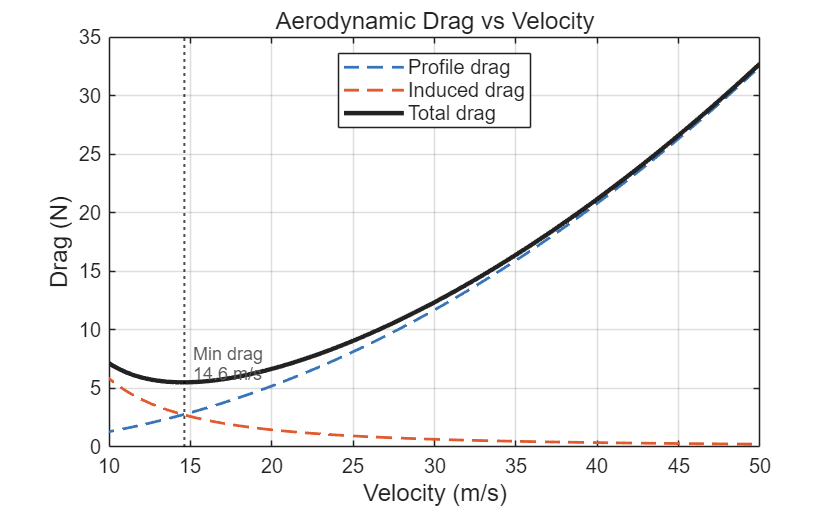

 
% Aerodynamic drag vs. velocity
m   = aircraft.mass;
S   = aircraft.Sref;
AR  = aircraft.AR;

V_range = linspace(5, 50, 300);



k = 1 / (pi * e * AR);

D_profile = 0.5 * rho * V_range.^2 * S * CD0;
D_induced = (k * (m*g)^2) ./ (0.5 * rho * V_range.^2 * S);
D_total   = D_profile + D_induced;
P_aero    = D_total .* V_range;

% Operating point from AVL trim
D_op  = 0.5 * rho * V^2 * S * (CD0 + avl.CDi);
P_op  = D_op * V;

[D_min, idx_min] = min(D_total);
V_min_drag = V_range(idx_min);
figure;
hold on;
plot(V_range, D_profile, '--', 'Color', '#3874B8', 'LineWidth', 1.4, ...
     'DisplayName', 'Profile drag')
plot(V_range, D_induced, '--', 'Color', '#E05C30', 'LineWidth', 1.4, ...
     'DisplayName', 'Induced drag')
plot(V_range, D_total,   '-',  'Color', '#222222', 'LineWidth', 2.2, ...
     'DisplayName', 'Total drag')
% plot(aero.V, D_op, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', ...
     % 'DisplayName', sprintf('XFLR5 cruise  (%.1f m/s)', aero.V))
xline(V_min_drag, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off')
text(V_min_drag + 0.5, D_min * 1.28, sprintf('Min drag\n%.1f m/s', V_min_drag), ...
     'FontSize', 9, 'Color', [0.35 0.35 0.35])
hold off;
xlabel('Velocity (m/s)', 'FontSize', 12)
ylabel('Drag (N)',        'FontSize', 12)
title('Aerodynamic Drag vs Velocity', 'FontSize', 12, 'FontWeight', 'normal')
legend('Location', 'north', 'FontSize', 10)
xlim([10, 50]);
grid on; box on;

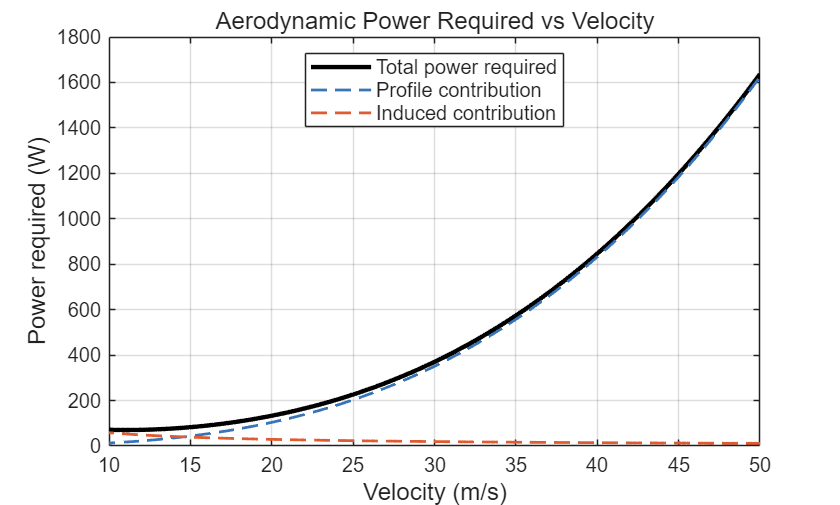

%% 3  ── Aerodynamic Power Required vs Velocity ───────────────────────────
% Power required = drag × velocity.
% This is the minimum power the motor must deliver to the air just to
% maintain level flight at each speed. Actual electrical power consumed
% will be higher once you account for motor and prop efficiency.

figure;
hold on;
plot(V_range, P_aero, 'k-',  'LineWidth', 2.2, 'DisplayName', 'Total power required')
plot(V_range, D_profile .* V_range, '--', 'Color', '#3874B8', ...
     'LineWidth', 1.4, 'DisplayName', 'Profile contribution')
plot(V_range, D_induced .* V_range, '--', 'Color', '#E05C30', ...
     'LineWidth', 1.4, 'DisplayName', 'Induced contribution')
% plot(aero.V, P_op, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', ...
%      'DisplayName', sprintf('Cruise point  (%.0f W aero)', P_op))
hold off;
xlabel('Velocity (m/s)',      'FontSize', 12)
ylabel('Power required (W)', 'FontSize', 12)
title('Aerodynamic Power Required vs Velocity', 'FontSize', 12, 'FontWeight', 'normal')
legend('Location', 'north', 'FontSize', 10)
xlim([10, 50]);
grid on; box on;

## Propeller Thrust

The aircraft's drag was half the equation. Now, the goal is to see how fast we can actually go. That means we're looking for an equilibrium. Luckily, everyone who's interviewed for DBF has been asked the question: what are the four main forces acting on an aircraft? In the horizontal direction, we know we're going to see drag balancing out thrust. Since we know the drag as a function of velocity, now it's time to do the same for thrust. 

%% 5  ── Thrust vs Velocity — Does the Plane Fly? ─────────────────────────
% Now sweep velocity. propMain calls propSim at each speed under the given
% throttle setting and fits a quadratic.
%
% Plotting thrust and drag on the same axes answers the key question:
% is thrust > drag at your target speed? The crossing point is where the
% plane reaches equilibrium — it can't go faster than that at this throttle.
cruise_throttle = 0.9;
 

[thrusts_fit_cruise, t_flights_fit_cruise, powers_fit_cruise, ~, velocities] = ...
    propMain(V_nom, cap_battery, use_battery, Kv, I0, Rm, ...
             cruise_throttle, prop_id, prop_data_library);

% [thrusts_fit_max, t_flights_fit_max, powers_fit_max, ~, ~] = ...
%     propMain(V_nom, cap_battery, use_battery, Kv, I0, Rm, ...
%              1.0, prop_id, prop_data_library);

T_cruise = polyval(thrusts_fit_cruise, V_range);
% T_max    = polyval(thrusts_fit_max,    V_range);

% Find equilibrium (thrust = drag crossing)
diff_sign = diff(sign(T_cruise - D_total));
idx_eq    = find(diff_sign ~= 0, 1, 'last');
V_eq      = NaN;
if ~isempty(idx_eq)
    V_eq = V_range(idx_eq); 
end

figure;
hold on;
% plot(V_range, T_max,    '-',  'Color', '#E05C30', 'LineWidth', 2.2, ...
%      'DisplayName', 'Thrust — full throttle')
plot(V_range, T_cruise, '-',  'Color', '#3874B8', 'LineWidth', 2.2, ...
     'DisplayName', sprintf('%.0f%% throttle', cruise_throttle*100))
if ~isnan(V_eq)
    plot(V_eq, polyval(thrusts_fit_cruise, V_eq), 'x', ...
         'MarkerSize', 13, 'LineWidth', 2.2, ...
         'DisplayName', sprintf('Equilibrium'))
end
plot(V_range, D_total,  'k--', 'LineWidth', 1.8, ...
     'DisplayName', 'Drag required')

fprintf("Equilibrium speed: %.1f", V_eq);

Equilibrium speed: 36.5

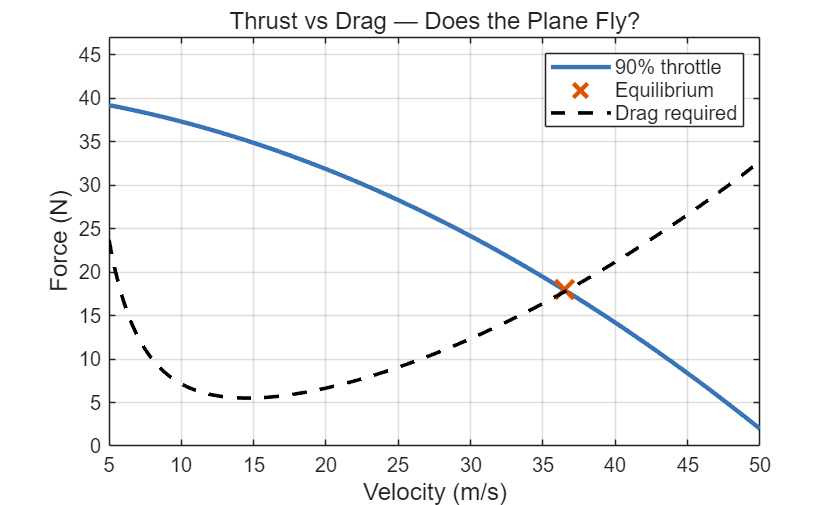


hold off;
xlabel('Velocity (m/s)', 'FontSize', 12)
ylabel('Force (N)',       'FontSize', 12)
title('Thrust vs Drag — Does the Plane Fly?', 'FontSize', 12, 'FontWeight', 'normal')
legend('Location', 'northeast', 'FontSize', 10)
grid on; box on;
ylim([0, max(T_cruise) * 1.2])

## Takeoff Run

Although static margin plays a roll in the elevator's ability to pitch us off the ground, if we assume that we can pitch up then we can calculate the distance required to lift-off speed.

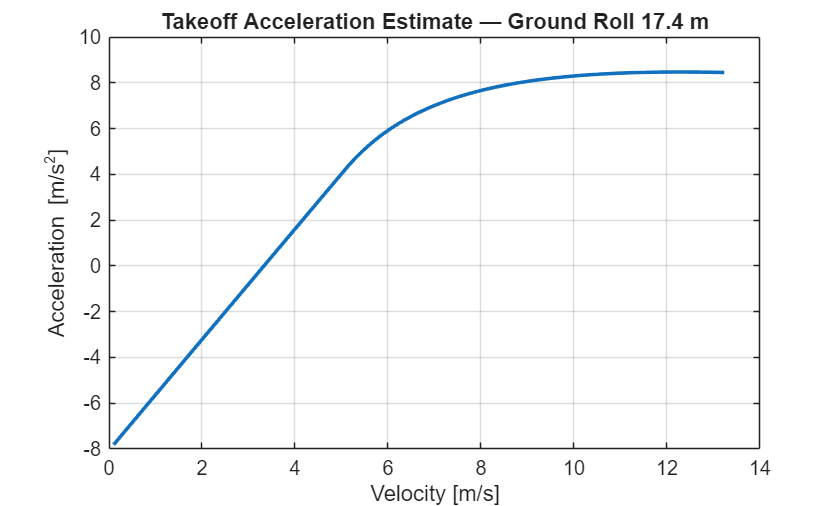

 
%% Takeoff Ground Roll Estimate

CL_takeoff = 0.8;      % estimate; tune this
mu_roll    = 0.04;     % rolling resistance estimate
CLmax = 1.3;
V_stall = sqrt(2 * aircraft.mass * g / (rho * S * CLmax));
V_rot      = 1.2 * V_stall;

V_to = linspace(0.1, V_rot, 300);

T_to = polyval(thrusts_fit_cruise, V_to);
D_to = interp1(V_range, D_total, V_to, 'linear', 'extrap');
L_to = 0.5 * rho .* V_to.^2 * S * CL_takeoff;

F_net = T_to - D_to - mu_roll * max(aircraft.mass * g - L_to, 0);
a_to  = F_net / aircraft.mass;

% Avoid division by zero or negative acceleration
valid = a_to > 0;
s_to = trapz(V_to(valid), V_to(valid) ./ a_to(valid));

% fprintf('\n=== Takeoff Estimate ===\n')
% fprintf('  Rotation speed = %.2f m/s\n', V_rot)
% fprintf('  Ground roll    = %.1f m\n', s_to)

figure;
plot(V_to, a_to, 'LineWidth', 1.8)
xlabel('Velocity [m/s]')
ylabel('Acceleration [m/s^2]')
title(sprintf('Takeoff Acceleration Estimate — Ground Roll %.1f m', s_to))
grid on; box on;

## Climbing Ability

So we know where the plane will level out, but what happens below that speed? Anytime thrust is greater than drag, there will be excess power in the system. In our basic analysis at a set speed, excess power will go into climb. Our rate of cilmb (ROC) is the excess power we have divided by the aircraft weight. So a super heavy plane can do less with excess power than a super light plane. As we speed up, drag increases, and there is a point where we do not have any more excess power (we're already putting all of our thrust into forward speed). That's when we can't climb any more.

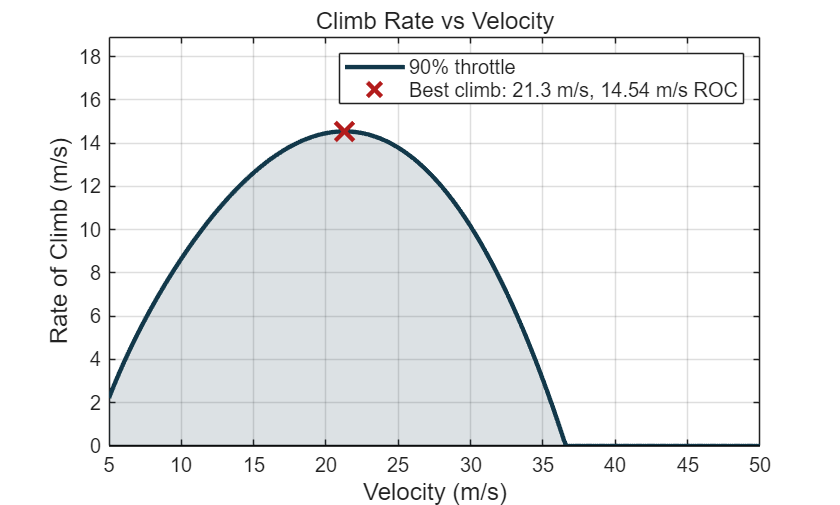

 
%% Climb Rate

W_aircraft = m * g;  % [N]  total weight

% Reuse V_range from the thrust/drag section above
T_full = polyval(thrusts_fit_cruise, V_range);     % [N] thrust at cruise throttle
P_excess = (T_full - D_total) .* V_range;           % [W] excess power

ROC = P_excess ./ W_aircraft;                       % [m/s]
ROC_clipped = max(ROC, 0);                          % only show positive climb

% Find peak ROC
[ROC_max, idx_max] = max(ROC_clipped);
V_best_climb = V_range(idx_max);

% fprintf('Best climb speed:  %.1f m/s\n', V_best_climb)
% fprintf('Peak climb rate:   %.2f m/s  (%.0f ft/min)\n', ROC_max, ROC_max * 196.85)

figure;
hold on;

% Shaded region under the climb curve
fill([V_range, fliplr(V_range)], ...
     [ROC_clipped, zeros(1, length(V_range))], ...
     [0.07 0.22 0.29], 'FaceAlpha', 0.15, 'EdgeColor', 'none', ...
     'HandleVisibility', 'off')

plot(V_range, ROC_clipped, '-', 'Color', [0.07 0.22 0.29], ...
     'LineWidth', 2.2, 'DisplayName', sprintf('%.0f%% throttle', cruise_throttle*100))

plot(V_best_climb, ROC_max, 'x', ...
     'MarkerSize', 13, 'LineWidth', 2.2, 'Color', [0.70 0.11 0.11], ...
     'DisplayName', sprintf('Best climb: %.1f m/s, %.2f m/s ROC', V_best_climb, ROC_max))

yline(0, 'k-', 'LineWidth', 1.0, 'HandleVisibility', 'off')

hold off;
xlabel('Velocity (m/s)', 'FontSize', 12)
ylabel('Rate of Climb (m/s)', 'FontSize', 12)
title('Climb Rate vs Velocity', 'FontSize', 12, 'FontWeight', 'normal')
legend('Location', 'northeast', 'FontSize', 10)
grid on; box on;
ylim([0, ROC_max * 1.3])

## Total Mission Scoring

Now the goal is to figure out how our plane would do at competition! We know everything about the performance of our plane, but we still have to "estimate" the performance of other aircraft to see where we would place. Math aside, this is probably the trickiest logic part of sizing. If you change around the "best" estimates to make them low, you'll find our plane gets more than 1 point in the mission score - this means we did better than the best team (i.e. we are the best team) and our analysis doesn't work anymore. Look out for this as you shift values!

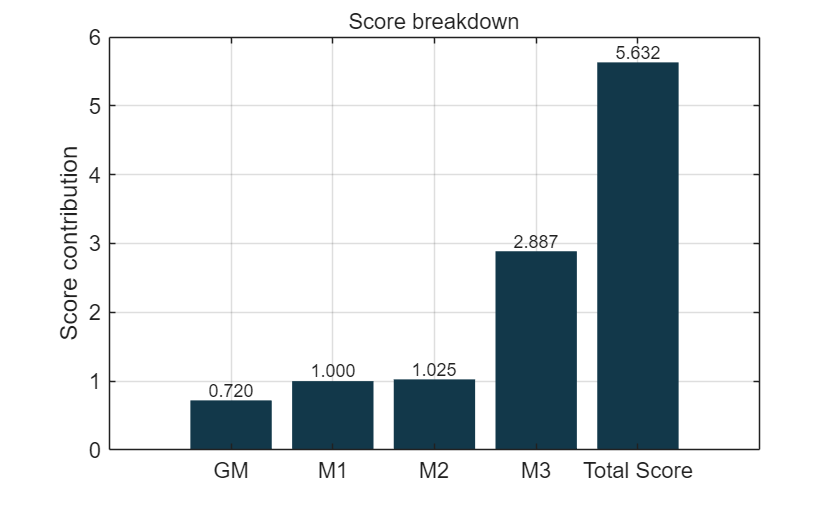

%% Scoring
% Lap times are the main unknowns — everything else pulls from the
% geometry and propulsion variables already defined above.
% Adjust the three lap times and scoring constants to see how your
% design choice affects total score.
 

% ── Lap times (fill in from flight sim or estimation) ─────────────────
l_lap = 900;              % [m] the distance of a single lap (roughly)
t_lap_m1 = l_lap / V_eq;    % [s]  single lap time, Mission 1
t_lap_m2 = l_lap / V_eq;    % [s]  single lap time, Mission 2
t_lap_m3 = l_lap / V_eq;    % [s]  single lap time, Mission 3 (banner tow)

% ── Ground mission constants ──────────────────────────────────────────
t_pass         = 2.5;    % [s]  time per passenger placement
t_cargo        = 1.5;    % [s]  time per cargo placement
t_banner       = 7;      % [s]  banner attach/detach time
best_t_mission = 18;     % [s]  reference time (best competitor)

% ── Mission 2 constants ───────────────────────────────────────────────
best_profit    = 1800;   % reference profit score

% ── Mission 3 reference values ────────────────────────────────────────
best_t_lap_m3  = 45;     % [s]   best competitor lap time
best_l_banner  = 300;    % [in]  best competitor banner length

% ── Pull from existing structs ────────────────────────────────────────
b_wing_ft  = aircraft.Bref * 3.28084;   % wingspan [ft]  (scoring uses feet)
num_pass   = geom.n_ducks;              % duck passengers
num_cargo  = geom.n_pucks;              % puck cargo
l_banner   = 140;              % banner length [in]  (from banner section)

% ── Run scoring ───────────────────────────────────────────────────────
gm_score = scoreGM(num_pass, t_pass, num_cargo, t_cargo, t_banner, best_t_mission);
m1_score = scoreM1(t_lap_m1);
m2_score = 0;
m3_score = 0;

if m1_score > 0
    m2_score = scoreM2(num_pass, num_cargo, t_lap_m2, cap_battery, V_nom, best_profit);
    if m2_score > 2
        fprintf("You scored higher than the max M2 score! Something's not right :/");
    end
    if m2_score > 0
        m3_score = scoreM3(b_wing_ft, t_lap_m3, l_banner, best_t_lap_m3, best_l_banner);
        if m3_score > 3
            fprintf("You scored higher than the max M3 score! Something's not right :/");
        end
    end
end

total_score     = gm_score + m1_score + m2_score + m3_score;
score_breakdown = [gm_score, m1_score, m2_score, m3_score, total_score];

% ── Print results ─────────────────────────────────────────────────────
% fprintf('\n=== Scoring Results ===\n')
% fprintf('  Ground Mission  = %.4f\n',  gm_score)
% fprintf('  Mission 1       = %.4f\n',  m1_score)
% fprintf('  Mission 2       = %.4f\n',  m2_score)
% fprintf('  Mission 3       = %.4f\n',  m3_score)
% fprintf('  ─────────────────────\n')
% fprintf('  Total Score     = %.4f\n',  total_score)

if m1_score == 0
    fprintf('\n  ⚠ M1 = 0 — M2 and M3 are gated out.\n')
elseif m2_score == 0
    fprintf('\n  ⚠ M2 = 0 — M3 is gated out.\n')
end

% ── Score bar chart ───────────────────────────────────────────────────
figure;
bar(score_breakdown, 'FaceColor', [0.07 0.22 0.29], 'EdgeColor', 'none')
set(gca, 'XTickLabel', {'GM', 'M1', 'M2', 'M3', 'Total Score'}, 'FontSize', 11)
ylabel('Score contribution')
title(sprintf('Score breakdown'), ...
    'FontSize', 11, 'FontWeight', 'normal')
grid on; box on;
for k = 1:5
    text(k, score_breakdown(k) + total_score*0.025, ...
        sprintf('%.3f', score_breakdown(k)), ...
        'HorizontalAlignment', 'center', 'FontSize', 9)
end